% Program P2_1
% Simulation of an M-point Moving Average Filter
% Generate the input signal
n = 0:100;
s1 = cos(2*pi*0.05*n); % A low frequency sinusoid
s2 = cos(2*pi*0.47*n); % A high frequency sinusoid
x = s1+s2;
% Implementation of the moving average filter


clf;
for M=1:5
    disp(M)
    % M = input('Desired length of the filter = ');
    % num = ones(1,M);
    num = (-1).^[0:M-1];
    y = filter(num,1,x)/M;
    % Display the input and output signals
    subplot(2,2,1);
    plot(n,s1);
    axis([0, 100, -2, 2]);
    xlabel('Time index n'); ylabel('Amplitude');
    title('Signal # 1');
    subplot(2,2,2);
    plot(n,s2);
    axis([0, 100, -2, 2]);
    xlabel('Time index n'); ylabel('Amplitude');
    title('Signal # 2');
    subplot(2,2,3);
    plot(n,x);
    axis([0, 100, -2, 2]);
    xlabel('Time index n'); ylabel('Amplitude');
    title('Input Signal');
    subplot(2,2,4);
    plot(n,y);
    axis([0, 100, -2, 2]);
    xlabel('Time index n'); ylabel('Amplitude');
    title('Output Signal');
    axis;
end

% Program P2_1
% Simulation of an M-point Moving Average Filter
% Generate the input signal
clf;
n = 0:100;
s1 = cos(2*pi*0.05*n); % A low frequency sinusoid
s2 = cos(2*pi*0.47*n); % A high frequency sinusoid
x = s1+s2;
% Implementation of the moving average filter

M_values = [1 2 7 10 20];
y_all = zeros(length(n), length(M_values));

for i = 1:length(M_values)
    M = M_values(i);
%     num = (-1).^[0:M-1];
    num = ones(1,M);
    y = filter(num,1,x)/M;
    y_all(:, i) = y; % store y for each M value
end

% Plot the input and output signals
subplot(2,2,1);
plot(n,s1);
axis([0, 100, -2, 2]);
xlabel('Time index n'); ylabel('Amplitude');
title('Signal # 1');

subplot(2,2,2);
plot(n,s2);
axis([0, 100, -2, 2]);
xlabel('Time index n'); ylabel('Amplitude');
title('Signal # 2');

subplot(2,2,3);
plot(n,x);
axis([0, 100, -2, 2]);
xlabel('Time index n'); ylabel('Amplitude');
title('Input Signal');

subplot(2,2,4);
plot(n, y_all);
axis([0, 100, -2, 2]);
xlabel('Time index n'); ylabel('Amplitude');
title('Output Signals for M');
legend('M = 1', 'M = 2', 'M = 7', 'M = 10', 'M = 20');

% Program P2_1
% Simulation of an M-point Moving Average Filter

% Generate the input signal
n = 0:100;

% Define the frequencies for s1 and s2
f1_values = [0.01, .04];
f2_values = [0.4, 0.7, .8, .9];

for i = 1:length(f1_values)
    f1 = f1_values(i);
    s1 = cos(2*pi*f1*n); % A low frequency sinusoid
    
    % Create a new figure for this value of f1
    figure;
    sgtitle(sprintf('f1 = %.2f', f1));
    
    for j = 1:length(f2_values)
        f2 = f2_values(j);
        s2 = cos(2*pi*f2*n); % A high frequency sinusoid
        x = s1+s2;

%         num = (-1).^[0:4];
        num = ones(1, 5);
        y = filter(num,1,x)/5;

        % Plot the input and output signals for this value of f2
        subplot(2,2,j);
        plot(n,s1, 'r', n,s2, 'b', n,x, 'g', n,y, 'm');
        axis([0, 100, -2, 2]);
        xlabel('Time index n'); ylabel('Amplitude');
        title(sprintf('f2 = %.2f', f2));
        legend({'Signal #1', 'Signal #2', 'Input Signal', 'Output Signal'});
    end
end

% Program Q2_4
% Modify P2_1 to use a swept frequency chirp input
% Generate the input signal
n = 0:100;
a = pi/200;
b = 0;
arg = a*n.*n + b*n;
x = cos(arg);
% Implementation of the moving average filter
M = input('Desired length of the filter = ');
num = ones(1,M);
y = filter(num,1,x)/M;
% Display the input and output signals
clf;
subplot(2,1,1);
plot(n, x);
axis([0, 100, -1.5, 1.5]);
xlabel('Time index n'); ylabel('Amplitude');
title('Input Signal');
subplot(2,1,2);
plot(n, y);
axis([0, 100, -1.5, 1.5]);
xlabel('Time index n'); ylabel('Amplitude');
title('Output Signal');
axis;

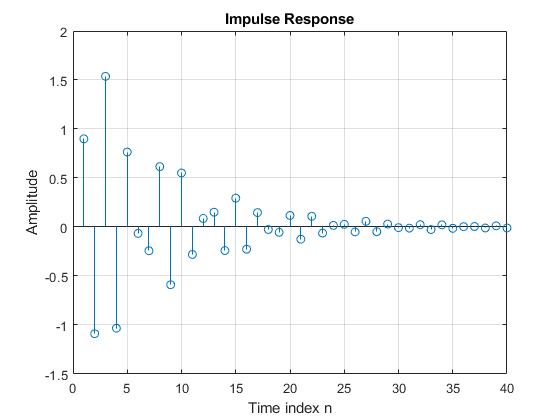

% Program Q2_20
% Compute the impulse response y using the filter command
clf;
num = [0.9 -0.45 0.35 0.002];
den = [1.0 0.71 -0.46 -0.62];

% Apply a unit impulse to the system
x = [1 zeros(1, 39)]; % Unit impulse at n=0

% Obtain the impulse response as the output of the system
y = filter(num, den, x);

% Plot the impulse response
stem(y);
xlabel('Time index n');
ylabel('Amplitude');
title('Impulse Response');
grid;

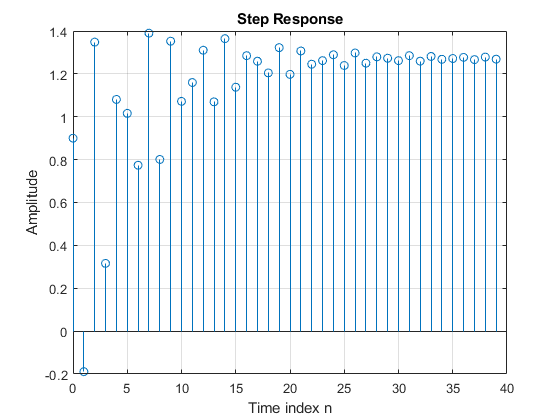

% Program to generate and plot the step response of a causal LTI system
clf;
num = [0.9 -0.45 0.35 0.002];
den = [1.0 0.71 -0.46 -0.62];

% Generate the step function
u = ones(1, 40);

% Compute the step response using the filter command
y = filter(num, den, u);

% Plot the step response
stem(0:39,y);
xlabel('Time index n');
ylabel('Amplitude');
title('Step Response');
grid;

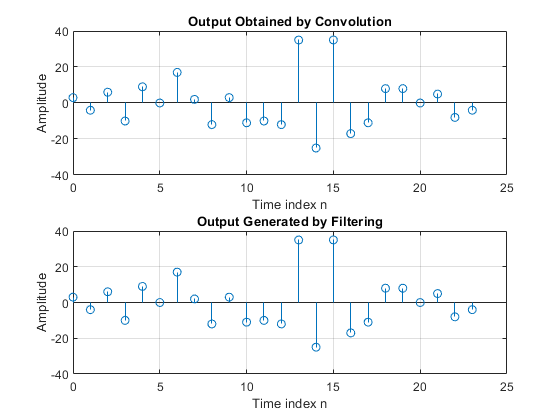

% Program to compute the convolution and filtering of a length-15 sequence with a length-10 sequence
clf;
h = [3 2 1 -2 1 0 -4 0 3 1 -2 3 -4 3 2]; % impulse response
x = [1 -2 3 -4 3 2 1 0 -1 -2]; % input sequence

% Compute the output using convolution
y_conv = conv(h, x);

% Compute the output using filtering
x1 = [x zeros(1, 15)];
y_filt = filter(h, 1, x1);

% Plot the outputs
n = 0:24;
subplot(2, 1, 1);
stem(0:23, y_conv);
xlabel('Time index n');
ylabel('Amplitude');
title('Output Obtained by Convolution');
grid;

subplot(2, 1, 2);
stem(0:23, y_filt(1:end-1));
xlabel('Time index n');
ylabel('Amplitude');
title('Output Generated by Filtering');
grid;

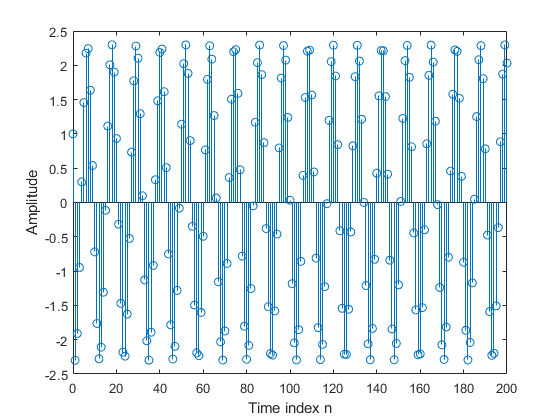

% Program P2_8
% Stability test based on the sum of the absolute
% values of the impulse response samples
clf;
den = [1 -1.7 +1]; num = [1 -4 3];
N = 200;
h = impz(num,den,N+1);
parsum = 0;
for k = 1:N+1;
parsum = parsum + abs(h(k));
if abs(h(k)) < 10^(-6), break, end
end
% Plot the impulse response
n = 0:N; stem(n,h); xlabel('Time index n'); ylabel('Amplitude');

% Print the value of abs(h(k))
disp('Value =');disp(abs(h(k)));

Value =
    2.0321

